# Default Mode Network

clc;clear;close all;
addpath Z:\xwiEEG_WorkingMemory_zhangshen\github_replication\function\iEEGPrep;
iEEGPrep_initial;
cd Z:\xwiEEG_WorkingMemory_zhangshen\github_replication\figS2_grayMatter_timeFrequency;
subG = {'sub-01', 'sub-02', 'sub-03', 'sub-05', 'sub-06', ...
    'sub-07', 'sub-09', 'sub-10', 'sub-11', 'sub-12', ...
    'sub-13', 'sub-14', 'sub-15', 'sub-16', 'sub-17', ...
    'sub-19', 'sub-20', 'sub-21', 'sub-23', 'sub-24'};
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
TFR = [];
for nSub = 1:length(subG)
    subID = subG{nSub};
    dataName = ['TFRmean_acrossAllRightTrials_', subID, '.mat'];
    data = load(fullfile('s3_TFRmeanAcrossAllRightTrials', dataName));
    load(fullfile('s0_data_afterPrep', [subID, '_electrodeMiddleRegionInfo.mat']));
    for n1 = 1:size(data.TFR, 1)
        chanName = f_strsplit(data.TFR{n1, 2}, subID);
        for nChan = 1:size(chanMiddleRegionInfo, 1)
            if strcmp(chanName, chanMiddleRegionInfo{nChan, 1})
                data.TFR{n1, 9} = chanMiddleRegionInfo{nChan, 8};
            end
        end
    end
    TFR = [TFR; data.TFR];
end
chanAtlasList1 = TFR(:, 3);
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
fsample = 250; foi1 = 4:0.25:13; foi2 = 13:1:120; foi = unique([foi1, foi2]);
N = 0; TFRsignals = []; chanAtlasList2 = {};
for nChan = 1:length(chanAtlasList1)
    if strcmp('Default', chanAtlasList1{nChan})
        N = N + 1;
        chanAtlasList2{N, 1} = TFR{nChan, 2};
        chanAtlasList2{N, 2} = TFR{nChan, 3};
        chanAtlasList2{N, 3} = TFR{nChan, 7};
        chanAtlasList2{N, 4} = TFR{nChan, 8};
        chanAtlasList2{N, 5} = TFR{nChan, 9};
        A = TFR{nChan, 1};
        A1 = A(:, 3*fsample+1:5*fsample);
        A2 = A(:, 5.5*fsample+1:7.5*fsample);
        A3 = A(:, 8*fsample+1:10*fsample);
        A = [A1, A2, A3];
        TFRsignals(:, :, N) = A;
    end
end
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
N = 0;
for nChan = 1:length(chanAtlasList2)
    if strcmp(chanAtlasList2{nChan, 3}, 'Temp') || chanAtlasList2{nChan, 5} == 1
        N = N + 1;
        TFRsignals2(:,:,N) = TFRsignals(:,:,nChan);
        chanAtlasList3{N, 1} = chanAtlasList2{nChan, 1};
        chanAtlasList3{N, 2} = chanAtlasList2{nChan, 2};
        chanAtlasList3{N, 3} = chanAtlasList2{nChan, 3};
        chanAtlasList3{N, 4} = chanAtlasList2{nChan, 4};
        chanAtlasList3{N, 5} = chanAtlasList2{nChan, 5};
    end
end
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
TFRsignalsS = TFRsignals2;
chanAtlasListS = chanAtlasList3;
disp(['Channel Number is: ', num2str(N)]);

Channel Number is: 78


savefolder = 's5_TFRloadingEffect_allRightTrials';
mkdir(savefolder);

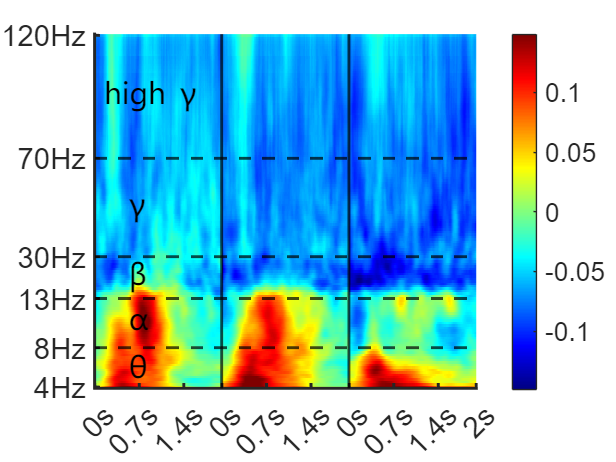

savename = fullfile(savefolder, 'TFRsignals_0b1b2b_CoreDMN.mat');
save(savename, 'TFRsignalsS', 'chanAtlasListS');
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
TFRmean = mean(TFRsignalsS, 3);
figure;
lims = min(abs(min(TFRmean(:))), abs(max(TFRmean(:))));
clims = [-lims, lims];
imagesc(TFRmean, clims);
axis xy; colorbar; colormap jet; hold on;
xline([2*fsample, 4*fsample], 'LineStyle', '-', 'Color', 'black', 'LineWidth', 2);
yline([17, 37, 54, 94], 'LineWidth', 2, 'LineStyle', '--', 'Color', [0 0 0]);
xticks([1:0.7*fsample:2*fsample, 2*fsample+(1:0.7*fsample:2*fsample), 4*fsample+(1:0.7*fsample:2*fsample), 6*fsample]);
xticklabels({'0s', '0.7s', '1.4s', '0s', '0.7s', '1.4s', '0s', '0.7s', '1.4s', '2s'});
yticks([1, 17, 37, 54, 94, 144]);
yticklabels({'4Hz', '8Hz', '13Hz', '30Hz', '70Hz', '120Hz'});
text([0.5*fsample, 0.5*fsample, 0.5*fsample, 0.5*fsample, 0.1*250], [7.5, 27, 45.5, 74, 119], ...
    {'\theta', '\alpha', '\beta', '\gamma', 'high \gamma'}, 'FontName', 'Bold', 'FontSize', 20);
set(gca, 'box', 'off', 'FontName', 'Arial', 'FontSize', 20, 'LineWidth', 2); 
hold off;

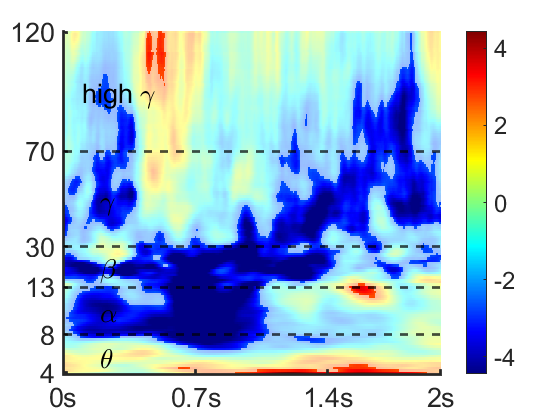

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
freqN = length(foi); timeN = 2*fsample;
pt_pairsample = zeros(freqN, timeN); t_pairsample = zeros(freqN, timeN);
TFR0b = TFRsignalsS(:, 1:2*fsample, :);
TFR2b = TFRsignalsS(:, 4*fsample+1:6*fsample, :);
for nFB = 1:freqN
    for nT = 1:timeN
        A = squeeze(TFR2b(nFB, nT, :)); 
        B = squeeze(TFR0b(nFB, nT, :));
        % Compute pair sample t-test between 2-back and 0-bakc
        [~, pt_pairsample(nFB, nT), ~, stats] = ttest(A, B, 'Tail', 'both');
        t_pairsample(nFB, nT) = stats.tstat;
    end
end
% view siginificant
figure;
clusterMask_pairsample = pt_pairsample<0.01;
lims = min(abs(min(t_pairsample(:))), abs(max(t_pairsample(:))));
clims = [-lims, lims];
imagesc(t_pairsample, clims);
axis xy; colorbar; colormap jet; hold on;
alphaData = ones(size(t_pairsample));
alphaData(clusterMask_pairsample == 0) = 0.4;
ax = gca();
set(ax.Children, 'AlphaData', alphaData);
set(ax, 'ALim', [0 1]);
yline([17, 37, 54, 94], 'LineWidth', 2, 'LineStyle', '--', 'Color', [0 0 0]);
xticks([1:0.7*fsample:2*fsample, 2*fsample]);
xticklabels({'0s', '0.7s', '1.4s', '2s'});
yticks([1, 17, 37, 54, 94, 144]);
yticklabels({'4', '8', '13', '30', '70', '120'});
text([0.2*fsample, 0.2*fsample, 0.2*fsample, 0.2*fsample, 0.1*250], [7.5, 27, 45.5, 74, 119], ...
    {'\theta', '\alpha', '\beta', '\gamma', 'high \gamma'}, 'FontName', 'Bold', 'FontSize', 20);
set(gca, 'box', 'off', 'FontName', 'Arial', 'FontSize', 20, 'LineWidth', 2); 
hold off;

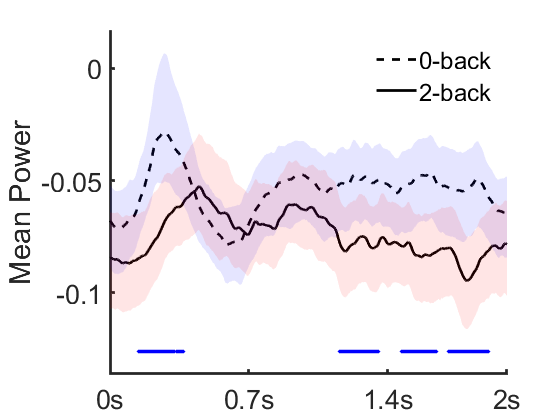

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
fB1 = 54; fB2 = 144;
pline_POS = zeros(size(TFR0b, 2), 1);
pline_NEG = zeros(size(TFR0b, 2), 1);
TFRline_0back = squeeze(mean(TFR0b(fB1:fB2, :, :), 1));
TFRline_2back= squeeze(mean(TFR2b(fB1:fB2, :, :), 1));
for nT = 1:size(TFR0b, 2)
    [~, pline_POS(nT), ~, ~] = ttest(TFRline_2back(nT, :), TFRline_0back(nT, :), 'Tail', 'right');
    [~, pline_NEG(nT), ~, ~] = ttest(TFRline_2back(nT, :), TFRline_0back(nT, :), 'Tail', 'left');
end
TFRline_2back_mean = mean(TFRline_2back, 2);
TFRline_2back_ci = bootci(2000, @mean, TFRline_2back');
TFRline_0back_mean = mean(TFRline_0back, 2);
TFRline_0back_ci = bootci(2000, @mean, TFRline_0back');
time = linspace(0, 2, length(TFRline_2back_mean));
pline_POS = mafdr(pline_POS', 'BHFDR', true);
pline_NEG = mafdr(pline_NEG', 'BHFDR', true);
% plot TFR mean line
figure; hold on;
colorG = [0, 0, 0];
plot(time, TFRline_0back_mean, 'LineStyle', '--', 'LineWidth', 2, 'Color', colorG);
plot(time, TFRline_2back_mean, 'LineStyle', '-', 'LineWidth', 2, 'Color', colorG);
% error shadow
shadowx = [time, fliplr(time)];
TFRline_2back_shadow = [TFRline_2back_ci(1, :), fliplr(TFRline_2back_ci(2, :))];
TFRline_0back_shadow = [TFRline_0back_ci(1, :), fliplr(TFRline_0back_ci(2, :))];       
fill(shadowx, TFRline_0back_shadow, 'b', 'FaceAlpha', 0.1, 'EdgeColor', 'none');
fill(shadowx, TFRline_2back_shadow, 'r', 'FaceAlpha', 0.1, 'EdgeColor', 'none');
ylimUpper = max([max(TFRline_0back_ci(:)), max(TFRline_2back_ci(:))]);
ylimLower = min([min(TFRline_0back_ci(:)), min(TFRline_2back_ci(:))]);
x = time(pline_POS < 0.01);
y = (ylimLower-0.01)*ones(size(x));
plot(x, y, 'r', 'LineStyle', 'none', 'Marker', '*', 'MarkerSize', 2);
x = time(pline_NEG < 0.01);
y = (ylimLower-0.01)*ones(size(x));
plot(x, y, 'b', 'LineStyle', 'none', 'Marker', '*', 'MarkerSize', 2);
ylim([ylimLower-0.02 ylimUpper+0.01]);
ylabel('Mean Power');
legend({'0-back', '2-back'}, 'Location', 'northeast', 'Box', 'off');
xticks([0, 0.7, 1.4, 2]);
xticklabels({'0s','0.7s','1.4s','2s'});
set(gca, 'box', 'off', 'FontName', 'Bold', 'FontSize', 20, 'LineWidth', 2); 
hold off;